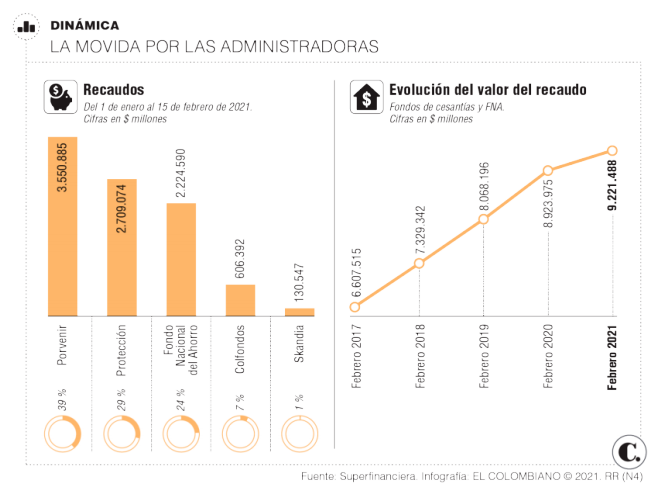

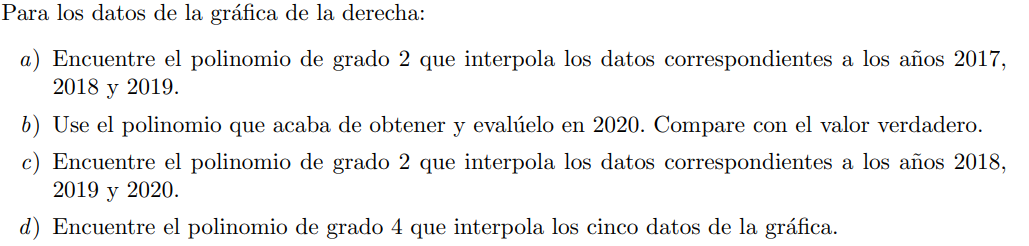

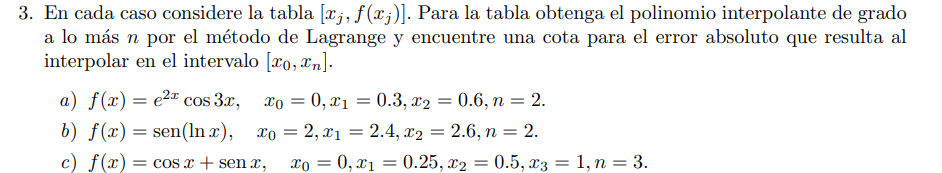

A)

f = @(x) exp(2*x).*cos(3*x)% funcion

f = function_handle with value:
    @(x)exp(2*x).*cos(3*x)


X = [0 0.3 0.6] %Nodos

X =          0    0.3000    0.6000


Y = f(X)

Y =     1.0000    1.1326   -0.7543


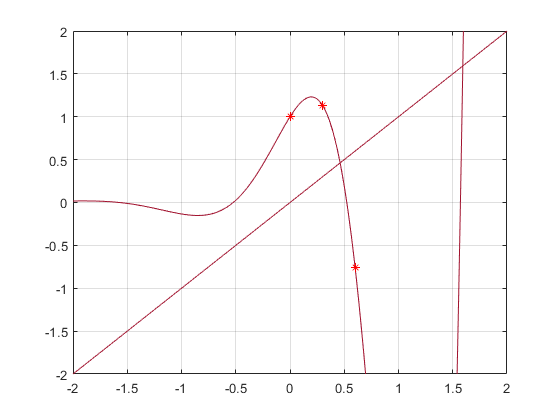

fplot(f)
hold on 
grid on
plot(X,Y,"*r") %Grafico de nodos en la funcion
xlim([-2 2])
ylim([-2 2])

[C, L] = lagran (X, Y)

C =   -11.2202    3.8082    1.0000


L =     5.5556   -5.0000    1.0000
  -11.1111    6.6667         0
    5.5556   -1.6667         0


%X son los nodos
%Y son imagenes de los nodos
%En esta entrada, C es el polinomio de Lagrange y L es el correspondiente
%L1,L2,L3,L4,Ln de la ecuaciones (Coeficiente polinomial)
%OJO: Los l van de menor a mayor, de L0, L1...,Ln en la matriz L del codigo.
% OJO: Los coeficientes en cada linea van de mayor a menor, de X^(n) hasta
% C, constante

PL2x = -11.2202*x^2 + 3.8082*x+ 1

B )

f = @(x) sin(log(x));
X = [2 2.4 2.6] % nodos

X =     2.0000    2.4000    2.6000


Y = f(X)

Y =     0.6390    0.7678    0.8166


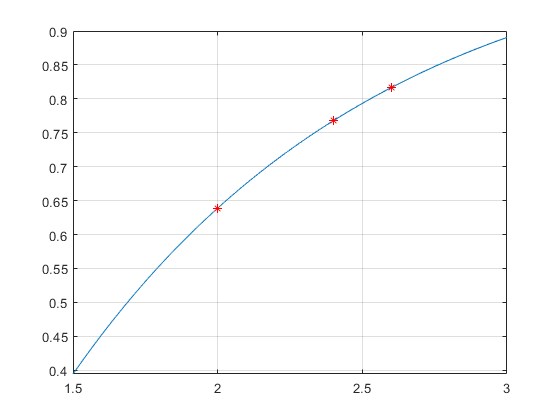

hold off

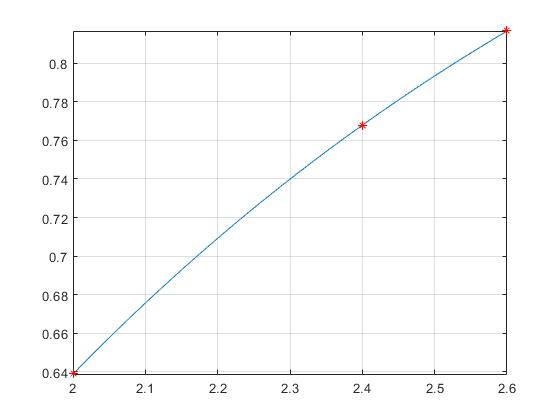

fplot(f)
hold on
grid on
plot(X,Y,"*r") %Grafico de nodos en la funcion
xlim([2 2.6])

[C, L] = lagran (X, Y)

C =    -0.1306    0.8970   -0.6325


L =     4.1667  -20.8333   26.0000
  -12.5000   57.5000  -65.0000
    8.3333  -36.6667   40.0000


% C es el polinomio de Lagrange

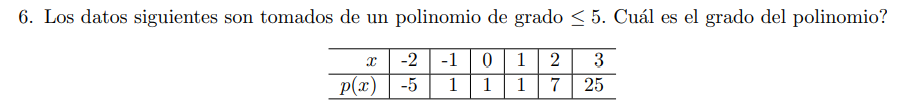

x = [-2 -1 0 1 2 3]

x =     -2    -1     0     1     2     3


y = [-5 1 1 1 7 25]

y =     -5     1     1     1     7    25


[C, D] = newpoly (x, y)

C =      0     0     1     0    -1     1


D =     -5     0     0     0     0     0
     1     6     0     0     0     0
     1     0    -3     0     0     0
     1     0     0     1     0     0
     7     6     3     1     0     0
    25    18     6     1     0     0


% El poliomio es de grado 3, pues hay una vble elevado a la 3.

X = [0 pi/2 pi]

X =          0    1.5708    3.1416


f = @(x) cos(pi*x);
Y = f(X)

Y =     1.0000    0.2206   -0.9027


[C, D] = newpoly (X, Y)

C =    -0.0697   -0.3867    1.0000


D =     1.0000         0         0
    0.2206   -0.4962         0
   -0.9027   -0.7151   -0.0697


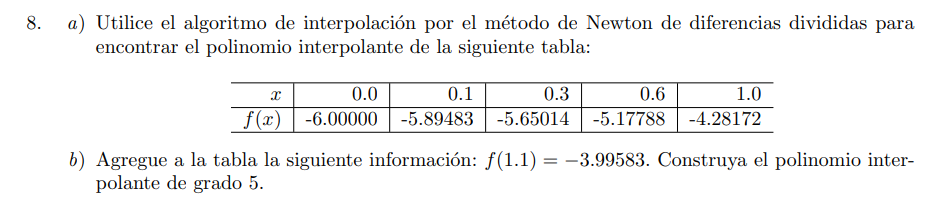

A)

X = [0 0.1 0.3 0.6 1]

X =          0    0.1000    0.3000    0.6000    1.0000


Y = [-6 -5.89483 -5.65014 -5.17788 -4.28172]

Y =    -6.0000   -5.8948   -5.6501   -5.1779   -4.2817


[C, D] = newpoly (X, Y)

C =     0.0630    0.1520    0.5035    0.9998   -6.0000


D =    -6.0000         0         0         0         0
   -5.8948    1.0517         0         0         0
   -5.6501    1.2234    0.5725         0         0
   -5.1779    1.5742    0.7015    0.2150         0
   -4.2817    2.2404    0.9517    0.2780    0.0630


% C es el polinomio 

B) 

X = [0 0.1 0.3 0.6 1 1.1]

X =          0    0.1000    0.3000    0.6000    1.0000    1.1000


Y = [-6 -5.89483 -5.65014 -5.17788 -4.28172 -3.99583]

Y =    -6.0000   -5.8948   -5.6501   -5.1779   -4.2817   -3.9958


[C, D] = newpoly (X, Y)

C =     0.0142    0.0347    0.1700    0.4994    1.0000   -6.0000


D =    -6.0000         0         0         0         0         0
   -5.8948    1.0517         0         0         0         0
   -5.6501    1.2234    0.5725         0         0         0
   -5.1779    1.5742    0.7015    0.2150         0         0
   -4.2817    2.2404    0.9517    0.2780    0.0630         0
   -3.9958    2.8589    1.2370    0.3566    0.0786    0.0142


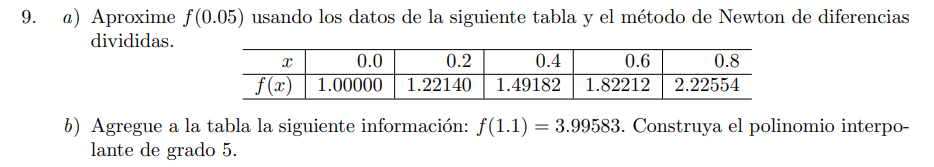

X = [0 0.2 0.4 0.6 0.8]

X =          0    0.2000    0.4000    0.6000    0.8000


Y = [1 1.22140 1.49182 1.82212 2.22554]

Y =     1.0000    1.2214    1.4918    1.8221    2.2255


[C, D] = newpoly (X, Y)

C =     0.0620    0.1519    0.5043    0.9996    1.0000


D =     1.0000         0         0         0         0
    1.2214    1.1070         0         0         0
    1.4918    1.3521    0.6127         0         0
    1.8221    1.6515    0.7485    0.2263         0
    2.2255    2.0171    0.9140    0.2758    0.0620


%C es el polinomio y es de grado 4. 

Pnew= @(x) 0.062*x^4+0.1419*x^3+0.5045*x^2+0.9996*x+1 % este es el polinomio

Pnew = function_handle with value:
    @(x)0.062*x^4+0.1419*x^3+0.5045*x^2+0.9996*x+1


Pnew(0.05)

ans = 1.0513

P = polyval(C,0.05)

P = 1.0513

%Ambos son los valores aproximados de f(0.05)

X = [0 0.2 0.4 0.6 0.8 1.1]

X =          0    0.2000    0.4000    0.6000    0.8000    1.1000


Y = [1 1.22140 1.49182 1.82212 2.22554 3.99583]

Y =     1.0000    1.2214    1.4918    1.8221    2.2255    3.9958


[C, D] = newpoly (X, Y)

C =     9.5550  -19.0480   13.5289   -3.3177    1.3665    1.0000


D =     1.0000         0         0         0         0         0
    1.2214    1.1070         0         0         0         0
    1.4918    1.3521    0.6127         0         0         0
    1.8221    1.6515    0.7485    0.2263         0         0
    2.2255    2.0171    0.9140    0.2758    0.0620         0
    3.9958    5.9010    7.7677    9.7910   10.5725    9.5550


El polinomio es 9.55x^5-19.04x^4... bueno, se saca de la C de la derecha ------------------------------------------------>

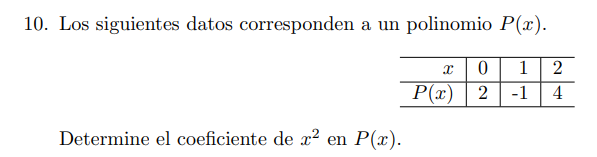

X = [0 1 2]

X =      0     1     2


Y= [2 -1 4]

Y =      2    -1     4


[C, D] = newpoly (X, Y)

C =      4    -7     2


D =      2     0     0
    -1    -3     0
     4     5     4


% El coeficiente es 4.